## Partial Derivatives, Jacobians & Polar Curves:

### 1.Partial Derivatives

% this question is already written in the record
% syms x y
% z=x^3+y^3+3*x*y
% z_x=diff(z,x)
% z_y=diff(z,y)
% z_x2=diff(z,x,2)
% z_y2=diff(z,y,2)
% z_xy=diff(z_x,y)

#

% this question is already written in the record
% syms x y
% u=(x^2+y^2)/x+y
% ux=diff(u,x)
% uy=diff(u,y)
% uxy=diff(ux,y)
% uyx=diff(uy,x)

#

syms x y
u=x^2-y^2;
v=2*x*y;
u_x=diff(u,x)

$$u\_x = 2\,x$$

u_y=diff(u,y)

$$u\_y = -2\,y$$

v_x=diff(v,x)

$$v\_x = 2\,y$$

v_y=diff(v,y)

$$v\_y = 2\,x$$

### 2.Jacobians

j=[u_x u_y;v_x v_y] 

$$j = \left(\begin{array}{cc} 2\,x & -2\,y\\ 2\,y & 2\,x \end{array}\right)$$

j=det(j)

$$j = 4\,x^{2}+4\,y^{2}$$

j=simplify(j)

$$j = 4\,x^{2}+4\,y^{2}$$

#### 2.2 Exercise:

%1
syms r t
x=r*cos(t);
y=r*sin(t);
ux=diff(x,t);
uy=diff(x,t);
vx=diff(y,t);
vy=diff(y,t);
j=jacobian([x,y],[r,t])

$$j = \left(\begin{array}{cc} \cos\left(t\right) & -r\,\sin\left(t\right)\\ \sin\left(t\right) & r\,\cos\left(t\right) \end{array}\right)$$

j=det(j)

$$j = r\,{\cos\left(t\right)}^{2}+r\,{\sin\left(t\right)}^{2}$$

j=simplify(j)

$$j = r$$

2

syms s t
x=r*cos(s)*cos(t);
y=r*cos(s)*sin(t);
z=r*sin(s);
j=jacobian([x,y,z],[r,s,t])

$$j = \left(\begin{array}{ccc} \cos\left(s\right)\,\cos\left(t\right) & -r\,\cos\left(t\right)\,\sin\left(s\right) & -r\,\cos\left(s\right)\,\sin\left(t\right)\\ \cos\left(s\right)\,\sin\left(t\right) & -r\,\sin\left(s\right)\,\sin\left(t\right) & r\,\cos\left(s\right)\,\cos\left(t\right)\\ \sin\left(s\right) & r\,\cos\left(s\right) & 0 \end{array}\right)$$

j=det(j)

$$j = -r^{2}\,{\cos\left(s\right)}^{3}\,{\cos\left(t\right)}^{2}-r^{2}\,{\cos\left(s\right)}^{3}\,{\sin\left(t\right)}^{2}-r^{2}\,\cos\left(s\right)\,{\cos\left(t\right)}^{2}\,{\sin\left(s\right)}^{2}-r^{2}\,\cos\left(s\right)\,{\sin\left(s\right)}^{2}\,{\sin\left(t\right)}^{2}$$

j=simplify(j)

$$j = -r^{2}\,\cos\left(s\right)$$

3

syms x y z
u=x+3*y^2-z^3;
v=4*x^3*y*z;
w=2*z^2-x*y;
j=jacobian([u,v,w],[x,y,z])

$$j = \left(\begin{array}{ccc} 1 & 6\,y & -3\,z^{2}\\ 12\,x^{2}\,y\,z & 4\,x^{3}\,z & 4\,x^{3}\,y\\ -y & -x & 4\,z \end{array}\right)$$

j=det(j)

$$j = 4\,x^{4}\,y-24\,x^{3}\,y^{3}+24\,x^{3}\,y\,z^{3}+16\,x^{3}\,z^{2}-288\,x^{2}\,y^{2}\,z^{2}$$

j=simplify(j)

$$j = 4\,x^{4}\,y-24\,x^{3}\,y^{3}+24\,x^{3}\,y\,z^{3}+16\,x^{3}\,z^{2}-288\,x^{2}\,y^{2}\,z^{2}$$

### 3.plotting a polar curve

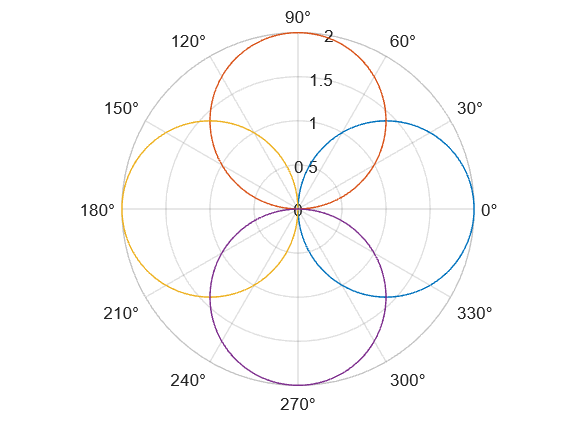

clear

theta=linspace(0,2*pi,100);
r1=2*cos(theta);
r2=2*sin(theta);
r3=-r1;
r4=-r2;
polarplot(theta,r1)
hold on
polarplot(theta,r2)
polarplot(theta,r3)
polarplot(theta,r4)
hold off

3.1Exercise

clear

1#

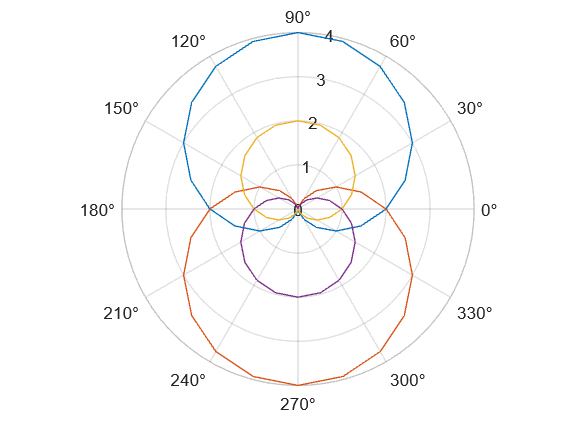

%r=2*(1+sintheta) and r2=-2(1+sintheta) from 0 to 2pi
theta=linspace(0,2*pi,25);
r1=2*(1+sin(theta));
r2=-r1;
polarplot(theta,r1)
hold on
r3=(1+sin(theta));
r4=-r3;
polarplot(theta,r2)
polarplot(theta,r3)
polarplot(theta,r4)
hold off

2#

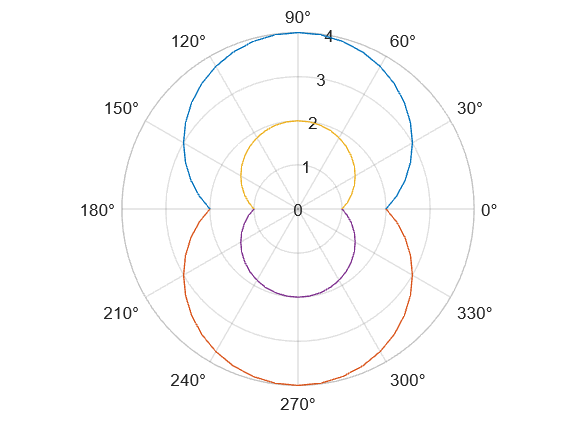

%r=2*(1+sintheta) and r2=-2(1+sintheta) from 0 to pi
theta=linspace(0,pi,25);
r1=2*(1+sin(theta));
r2=-r1;
polarplot(theta,r1)
hold on
r3=(1+sin(theta));
r4=-r3;
polarplot(theta,r2)
polarplot(theta,r3)
polarplot(theta,r4)
hold off

3#

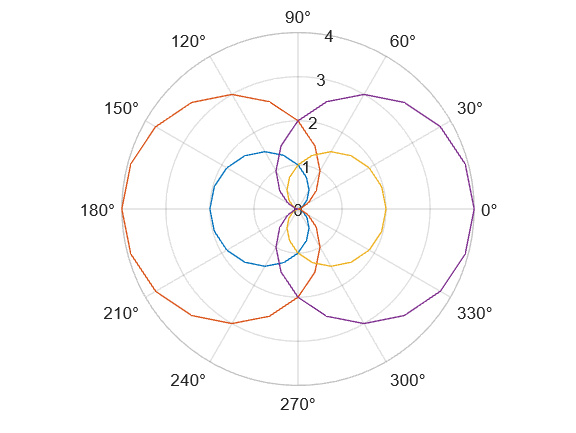

clear
%r=1-costheta and r2=2(1-costheta) from pi to 3pi
theta=linspace(pi,3*pi,25);
r1=(1-cos(theta));
r2=2*r1;
polarplot(theta,r1)
r3=-1*(1-cos(theta));
r4=2*r3;
hold on
polarplot(theta,r2)
polarplot(theta,r3)
polarplot(theta,r4)
hold off

7#

%obtain the graphs of all the above polar curves in the interval pi/2 to
%3*pi/2
theta=linspace(pi/2,(3*pi)/2,100)

theta =     1.5708    1.6025    1.6343    1.6660    1.6977    1.7295    1.7612    1.7929    1.8247    1.8564    1.8881    1.9199    1.9516    1.9833    2.0151    2.0468    2.0785    2.1103    2.1420    2.1737    2.2055    2.2372    2.2689    2.3007    2.3324    2.3641    2.3959    2.4276    2.4593    2.4911    2.5228    2.5545    2.5863    2.6180    2.6497    2.6815    2.7132    2.7449    2.7767    2.8084    2.8401    2.8719    2.9036    2.9353    2.9671    2.9988    3.0305    3.0623    3.0940    3.1257


r1=2*cos(theta)

r1 =     0.0000   -0.0635   -0.1268   -0.1901   -0.2532   -0.3160   -0.3785   -0.4406   -0.5023   -0.5635   -0.6241   -0.6840   -0.7433   -0.8019   -0.8596   -0.9165   -0.9724   -1.0274   -1.0813   -1.1341   -1.1858   -1.2363   -1.2856   -1.3335   -1.3802   -1.4254   -1.4692   -1.5115   -1.5523   -1.5915   -1.6292   -1.6651   -1.6995   -1.7321   -1.7629   -1.7920   -1.8193   -1.8447   -1.8683   -1.8900   -1.9098   -1.9277   -1.9436   -1.9576   -1.9696   -1.9796   -1.9877   -1.9937   -1.9977   -1.9997


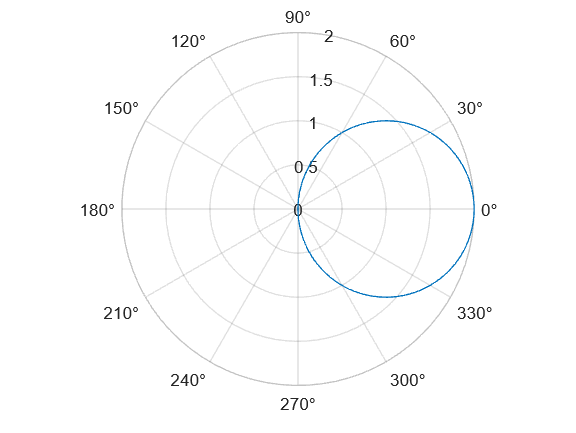

polarplot(theta,r1)

r2=2*sin(theta)

r2 =     2.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112    1.1601    1.1078    1.0545    1.0000    0.9445    0.8881    0.8308    0.7727    0.7138    0.6541    0.5938    0.5329    0.4715    0.4096    0.3473    0.2846    0.2217    0.1585    0.0952    0.0317


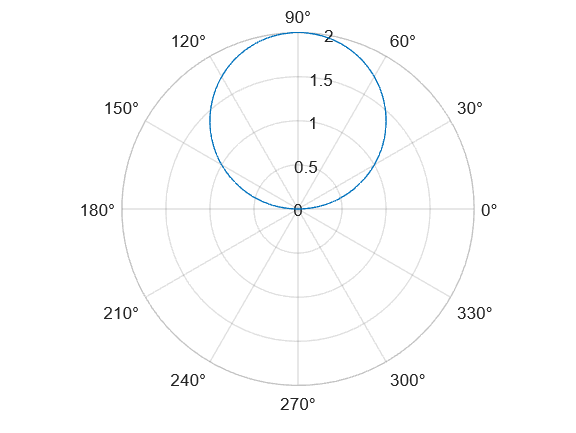

polarplot(theta,r2)

r3=-r1

r3 =    -0.0000    0.0635    0.1268    0.1901    0.2532    0.3160    0.3785    0.4406    0.5023    0.5635    0.6241    0.6840    0.7433    0.8019    0.8596    0.9165    0.9724    1.0274    1.0813    1.1341    1.1858    1.2363    1.2856    1.3335    1.3802    1.4254    1.4692    1.5115    1.5523    1.5915    1.6292    1.6651    1.6995    1.7321    1.7629    1.7920    1.8193    1.8447    1.8683    1.8900    1.9098    1.9277    1.9436    1.9576    1.9696    1.9796    1.9877    1.9937    1.9977    1.9997


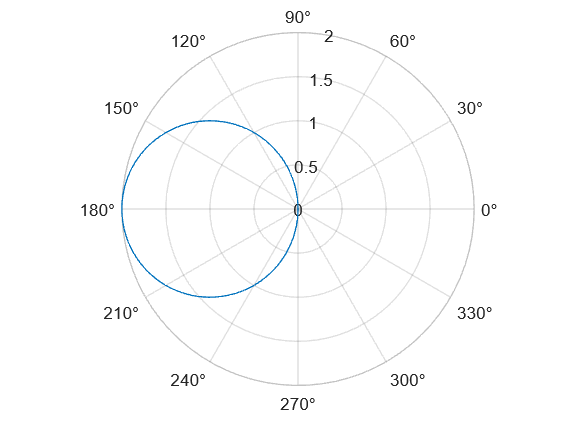

polarplot(theta,r3)

r4=-r2

r4 =    -2.0000   -1.9990   -1.9960   -1.9909   -1.9839   -1.9749   -1.9639   -1.9509   -1.9359   -1.9190   -1.9001   -1.8794   -1.8567   -1.8322   -1.8059   -1.7777   -1.7477   -1.7160   -1.6825   -1.6474   -1.6105   -1.5721   -1.5321   -1.4905   -1.4475   -1.4029   -1.3570   -1.3097   -1.2611   -1.2112   -1.1601   -1.1078   -1.0545   -1.0000   -0.9445   -0.8881   -0.8308   -0.7727   -0.7138   -0.6541   -0.5938   -0.5329   -0.4715   -0.4096   -0.3473   -0.2846   -0.2217   -0.1585   -0.0952   -0.0317


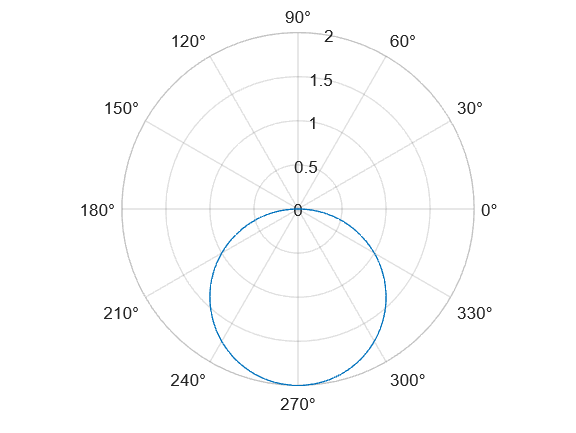

polarplot(theta,r4)

r5=2*(1+sin(theta))

r5 =     4.0000    3.9990    3.9960    3.9909    3.9839    3.9749    3.9639    3.9509    3.9359    3.9190    3.9001    3.8794    3.8567    3.8322    3.8059    3.7777    3.7477    3.7160    3.6825    3.6474    3.6105    3.5721    3.5321    3.4905    3.4475    3.4029    3.3570    3.3097    3.2611    3.2112    3.1601    3.1078    3.0545    3.0000    2.9445    2.8881    2.8308    2.7727    2.7138    2.6541    2.5938    2.5329    2.4715    2.4096    2.3473    2.2846    2.2217    2.1585    2.0952    2.0317


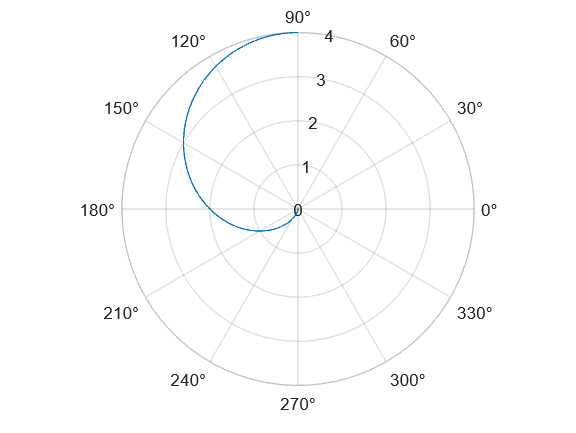

polarplot(theta,r5)

r6=-r5

r6 =    -4.0000   -3.9990   -3.9960   -3.9909   -3.9839   -3.9749   -3.9639   -3.9509   -3.9359   -3.9190   -3.9001   -3.8794   -3.8567   -3.8322   -3.8059   -3.7777   -3.7477   -3.7160   -3.6825   -3.6474   -3.6105   -3.5721   -3.5321   -3.4905   -3.4475   -3.4029   -3.3570   -3.3097   -3.2611   -3.2112   -3.1601   -3.1078   -3.0545   -3.0000   -2.9445   -2.8881   -2.8308   -2.7727   -2.7138   -2.6541   -2.5938   -2.5329   -2.4715   -2.4096   -2.3473   -2.2846   -2.2217   -2.1585   -2.0952   -2.0317


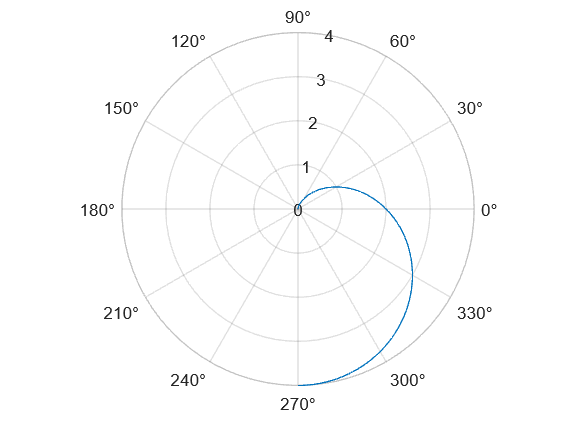

polarplot(theta,r6)

r7=1+sin(theta)

r7 =     2.0000    1.9995    1.9980    1.9955    1.9920    1.9874    1.9819    1.9754    1.9679    1.9595    1.9501    1.9397    1.9284    1.9161    1.9029    1.8888    1.8738    1.8580    1.8413    1.8237    1.8053    1.7861    1.7660    1.7453    1.7237    1.7015    1.6785    1.6549    1.6306    1.6056    1.5801    1.5539    1.5272    1.5000    1.4723    1.4441    1.4154    1.3863    1.3569    1.3271    1.2969    1.2665    1.2358    1.2048    1.1736    1.1423    1.1108    1.0792    1.0476    1.0159


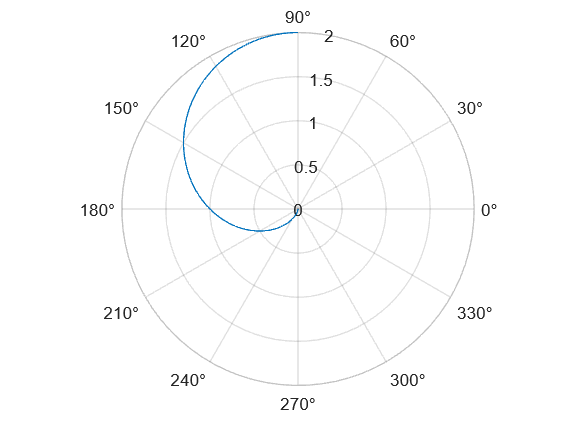

polarplot(theta,r7)

r8=-r7

r8 =    -2.0000   -1.9995   -1.9980   -1.9955   -1.9920   -1.9874   -1.9819   -1.9754   -1.9679   -1.9595   -1.9501   -1.9397   -1.9284   -1.9161   -1.9029   -1.8888   -1.8738   -1.8580   -1.8413   -1.8237   -1.8053   -1.7861   -1.7660   -1.7453   -1.7237   -1.7015   -1.6785   -1.6549   -1.6306   -1.6056   -1.5801   -1.5539   -1.5272   -1.5000   -1.4723   -1.4441   -1.4154   -1.3863   -1.3569   -1.3271   -1.2969   -1.2665   -1.2358   -1.2048   -1.1736   -1.1423   -1.1108   -1.0792   -1.0476   -1.0159


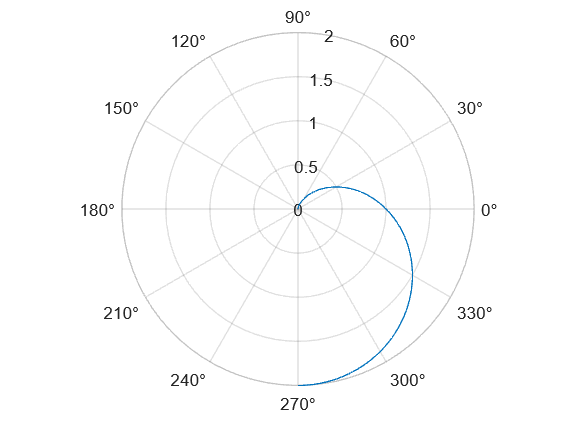

polarplot(theta,r8)

r9=1-cos(theta)

r9 =     1.0000    1.0317    1.0634    1.0951    1.1266    1.1580    1.1893    1.2203    1.2511    1.2817    1.3120    1.3420    1.3717    1.4009    1.4298    1.4582    1.4862    1.5137    1.5406    1.5671    1.5929    1.6182    1.6428    1.6668    1.6901    1.7127    1.7346    1.7557    1.7761    1.7958    1.8146    1.8326    1.8497    1.8660    1.8815    1.8960    1.9096    1.9224    1.9341    1.9450    1.9549    1.9638    1.9718    1.9788    1.9848    1.9898    1.9938    1.9969    1.9989    1.9999


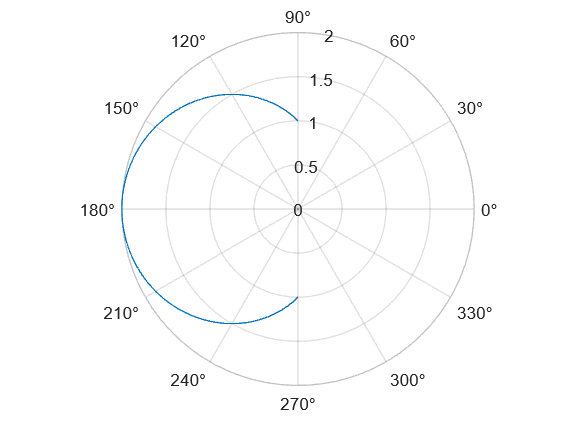

polarplot(theta,r9)

r10=2*r9

r10 =     2.0000    2.0635    2.1268    2.1901    2.2532    2.3160    2.3785    2.4406    2.5023    2.5635    2.6241    2.6840    2.7433    2.8019    2.8596    2.9165    2.9724    3.0274    3.0813    3.1341    3.1858    3.2363    3.2856    3.3335    3.3802    3.4254    3.4692    3.5115    3.5523    3.5915    3.6292    3.6651    3.6995    3.7321    3.7629    3.7920    3.8193    3.8447    3.8683    3.8900    3.9098    3.9277    3.9436    3.9576    3.9696    3.9796    3.9877    3.9937    3.9977    3.9997


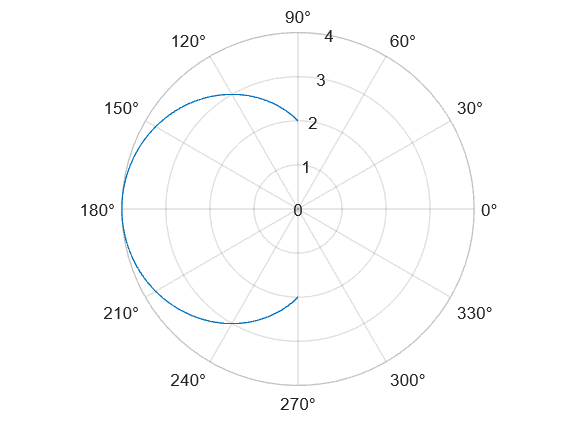

polarplot(theta,r10)

r11=-1*(1-cos(theta))

r11 =    -1.0000   -1.0317   -1.0634   -1.0951   -1.1266   -1.1580   -1.1893   -1.2203   -1.2511   -1.2817   -1.3120   -1.3420   -1.3717   -1.4009   -1.4298   -1.4582   -1.4862   -1.5137   -1.5406   -1.5671   -1.5929   -1.6182   -1.6428   -1.6668   -1.6901   -1.7127   -1.7346   -1.7557   -1.7761   -1.7958   -1.8146   -1.8326   -1.8497   -1.8660   -1.8815   -1.8960   -1.9096   -1.9224   -1.9341   -1.9450   -1.9549   -1.9638   -1.9718   -1.9788   -1.9848   -1.9898   -1.9938   -1.9969   -1.9989   -1.9999


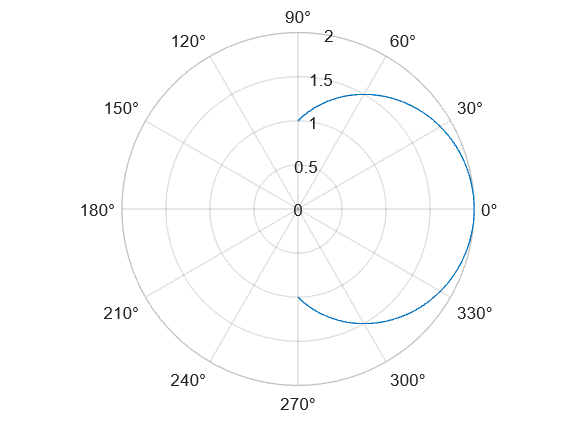

polarplot(theta,r11)

r12=2*r11

r12 =    -2.0000   -2.0635   -2.1268   -2.1901   -2.2532   -2.3160   -2.3785   -2.4406   -2.5023   -2.5635   -2.6241   -2.6840   -2.7433   -2.8019   -2.8596   -2.9165   -2.9724   -3.0274   -3.0813   -3.1341   -3.1858   -3.2363   -3.2856   -3.3335   -3.3802   -3.4254   -3.4692   -3.5115   -3.5523   -3.5915   -3.6292   -3.6651   -3.6995   -3.7321   -3.7629   -3.7920   -3.8193   -3.8447   -3.8683   -3.8900   -3.9098   -3.9277   -3.9436   -3.9576   -3.9696   -3.9796   -3.9877   -3.9937   -3.9977   -3.9997


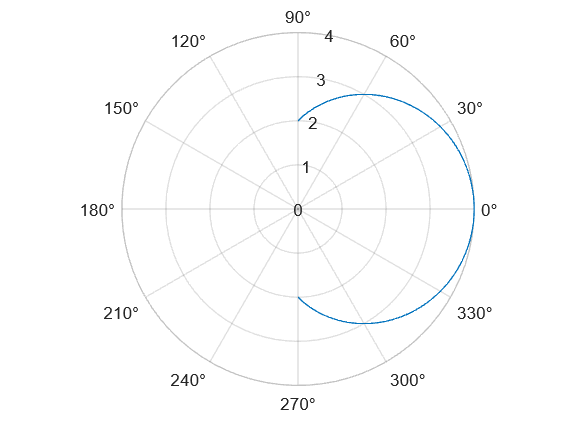

polarplot(theta,r12)